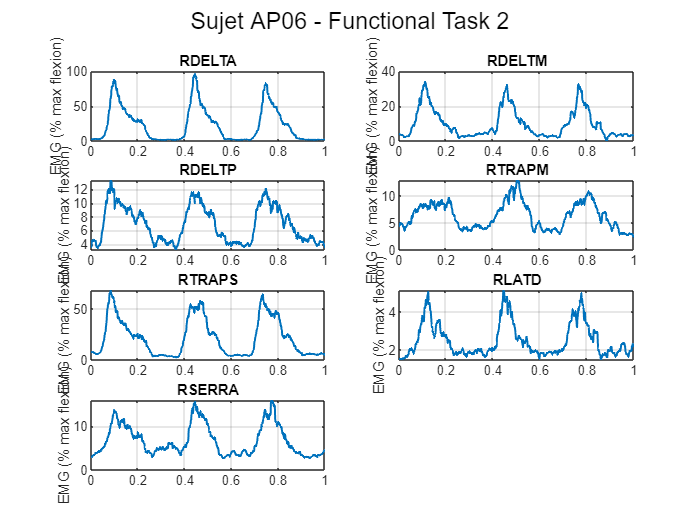

clc, clear all; 

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition des sujets
subjects = {'AP06'};
nb_subjects = length(subjects);

% Définition des muscles 
muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
nb_muscles = length(muscles);

% Définition des labels pour les tâches
functional_labels = {'Functional Task 1', 'Functional Task 2', 'Functional Task 3', 'Functional Task 4'};
analytic_labels = {'Analytic Task 1', 'Analytic Task 2', 'Analytic Task 3', 'Analytic Task 4'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Sélection de l'analytique et du fonctionnel 
selected_analytic = input('Choisissez une tâche analytique (1-4): ');
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);

% Initialisation des MVCs
mvc_flexion = zeros(nb_muscles, 1);
all_functional_data = cell(nb_subjects, nb_functional, nb_muscles);

% Traitement de la tâche analytique choisie
for subj_idx = 1:nb_subjects
    fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_analytic);
    
    c3dH_analytic = btkReadAcquisition(fileName_analytic);
    analogs_analytic = btkGetAnalogs(c3dH_analytic);
    
    for m = 1:nb_muscles
        muscle_name = muscles{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(signal_filtered);
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            mvc_flexion(m) = max(emg_rms);
        end
    end
end
mvc_max = max(mvc_flexion);

% Traitement et normalisation de la tâche fonctionnelle choisie
for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    figure;
    sgtitle(sprintf('Sujet %s - %s', subjects{subj_idx}, functional_labels{selected_functional}));
    
    for m = 1:nb_muscles
        subplot(ceil(nb_muscles/2), 2, m);
        muscle_name = muscles{m};
        if isfield(analogs_functional, muscle_name)
            signal = analogs_functional.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(signal_filtered);
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            emg_normalized = (emg_rms / mvc_max) * 100;
            interp_signal_functional = interp1(linspace(0, 1, length(signal)), emg_normalized, time_normalized, 'spline');
            all_functional_data{subj_idx, selected_functional, m} = interp_signal_functional;
            plot(time_normalized, interp_signal_functional, 'LineWidth', 1.2);
            title(muscle_name);
            ylabel('EMG (% max flexion)');
            grid on;
        else
            title(sprintf('%s (Données absentes)', muscle_name));
        end
    end
end


%% Calcul du VAF et détermination du nombre optimal de synergies 
subject_idx = 1;
functional_idx = selected_functional;

% Construction de la matrice de données :
% Chaque ligne correspond à un muscle et chaque colonne à un point temporel.
data_matrix = zeros(nb_muscles, num_points);
for m = 1:nb_muscles
    data_matrix(m, :) = all_functional_data{subject_idx, functional_idx, m};
end

% Paramètres pour le calcul du VAF
max_synergies = min(10, nb_muscles);   % On teste jusqu'à 10 synergies ou le nombre de muscles
VAF_threshold = 0.90;                   % Seuil de VAF à atteindre (90%)
VAF_values = zeros(1, max_synergies);   % Pour stocker le VAF calculé pour chaque nombre de synergies
optimal_synergies = max_synergies;       % Valeur par défaut si le seuil n'est jamais atteint
foundOptimal = false;                   % Indique si le seuil a été dépassé pour la première fois

% Boucle pour la décomposition NNMF et le calcul du VAF
for s = 1:max_synergies
    % Décomposition NNMF pour s synergies
    [W, H] = nnmf(data_matrix, s);
    
    % Reconstruction du signal
    X_reconstructed = W * H;
    
    % Calcul du VAF : Variance Accounted For
    VAF_values(s) = 1 - (sum(sum((data_matrix - X_reconstructed).^2)) / sum(sum(data_matrix.^2)));
    
    % Si le VAF dépasse le seuil et que c'est la première fois, mémoriser ce nombre de synergies
    if (VAF_values(s) >= VAF_threshold) && (~foundOptimal)
        optimal_synergies = s;
        foundOptimal = true;
    end
end


% Affichage du résultat dans la console
fprintf('Nombre optimal de synergies pour le sujet %s et la tâche %s : %d (VAF = %.2f%%)\n', ...
    subjects{subject_idx}, functional_labels{functional_idx}, optimal_synergies, VAF_values(optimal_synergies)*100);

Nombre optimal de synergies pour le sujet AP06 et la tâche Functional Task 2 : 1 (VAF = 96.27%)


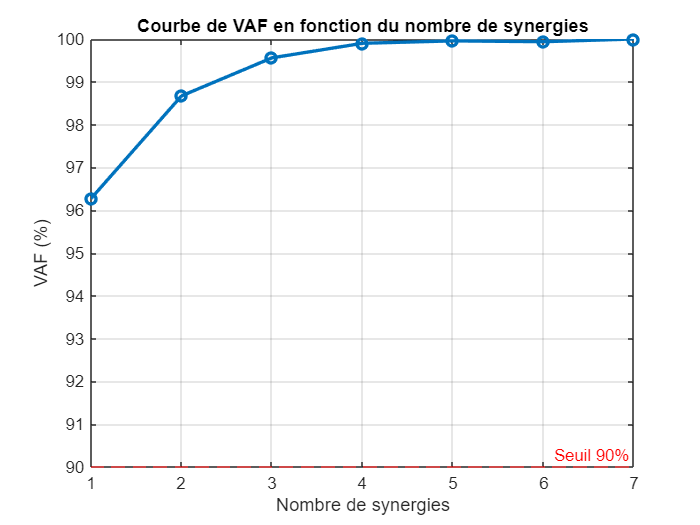


% Tracé de la courbe du VAF en fonction du nombre de synergies
figure;
plot(1:max_synergies, VAF_values*100, '-o', 'LineWidth', 2);
hold on;
yline(VAF_threshold*100, 'r--', 'Seuil 90%');
xlabel('Nombre de synergies');
ylabel('VAF (%)');
title('Courbe de VAF en fonction du nombre de synergies');
grid on;

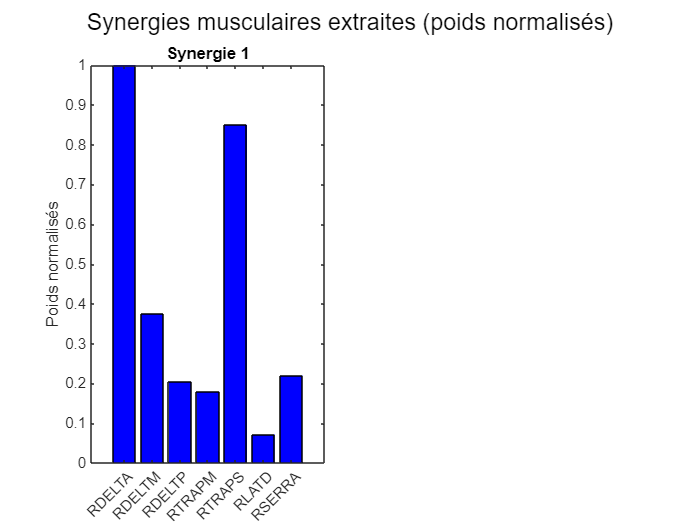


%% Visualisation des synergies musculaires extraites
% Recalcul de la décomposition NNMF avec le nombre optimal de synergies
[W, H] = nnmf(data_matrix, optimal_synergies);

% Optionnel : Normalisation de chaque colonne de W pour obtenir des valeurs entre 0 et 1
W_norm = zeros(size(W));
for i = 1:size(W,2)
    if max(W(:, i)) ~= 0
        W_norm(:, i) = W(:, i) / max(W(:, i));
    else
        W_norm(:, i) = W(:, i);
    end
end

% Visualisation : affichage des poids de chaque synergie
figure;
sgtitle('Synergies musculaires extraites (poids normalisés)');
for i = 1:optimal_synergies
    subplot(ceil(optimal_synergies/2), 2, i);
    bar(W_norm(:, i), 'FaceColor', 'b');
    title(['Synergie ', num2str(i)]);
    xticks(1:nb_muscles);
    xticklabels(muscles);
    xtickangle(45);
    ylabel('Poids normalisés');
end

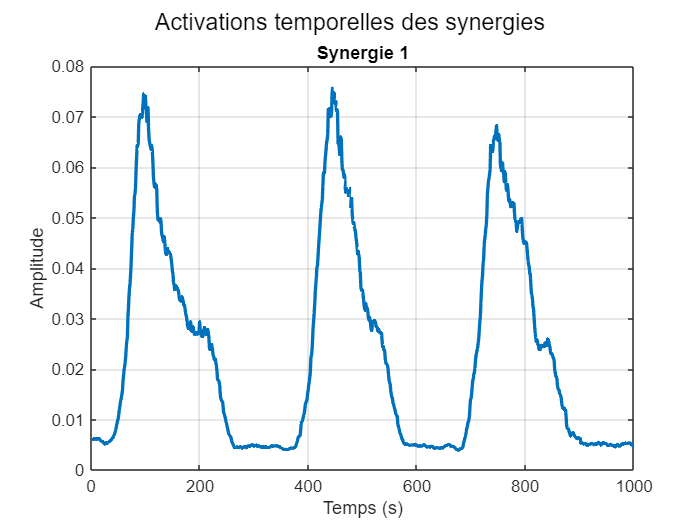


% Visualisation des activations temporelles des synergies

C = H;  % Activation temporelle des synergies

figure;
set(gcf, 'Name', 'Étape 6', 'NumberTitle', 'off');
sgtitle('Activations temporelles des synergies');

for i = 1:optimal_synergies
    subplot(optimal_synergies, 1, i);
    plot(C(i, :), 'LineWidth', 2);
    title(['Synergie ', num2str(i)]);
    grid on;
end
xlabel('Temps (s)');
ylabel('Amplitude');